#  Técnicas de procesamiento de señales y datos (MUIE)

## Ejercicio práctico bloque 4.1.1. Muestreo de señales (v3.0)

### Objetivo

El objetivo de este ejercicio es la comprension del impacto de la frecuencia de muestreo en la apariencia de una señal y sus implicaciones en el espectro DFT de las mismas. Disculpad que a veces no aparezcan tildes, pero al cambiar de version de matlab, hay un bug que no permite escribirlas.

### Desarrollo

Se dispone de una señal x(t) sinusoidal de amplitud 2, frecuencia 750Hz y de duración 5 periodos. Implemente un script en Matlab que realice las siguientes acciones:

- Borre variables, figuras y ventana de comandos:

clear all;
close all force;
clc;

- Genere dos señales discretas x1[n] y x2[n], muestreando x(t) a 2KHz y a 4KHz, respectivamente.

f            = 750;
numPeriods   = 5;
timeDuration = numPeriods * 1 / f;
amplitude    = 2;
fs1          = 2000;
fs2          = 4000;
[ x1, numSamples1, timeIndexes1 ] = generateSignal(fs1, timeDuration, f, amplitude, 0);
[ x2, numSamples2, timeIndexes2 ] = generateSignal(fs2, timeDuration, f, amplitude, 0); 

- Dibuje x1[n] y x2[n] y trate de encontrar una justificación a lo que observe. Si quiere puede ir subiendo progresivamente la frecuencia de muestreo para ver su impacto en el resultado. Escriba brevemente y en un comentario de su código dicha justificación. 

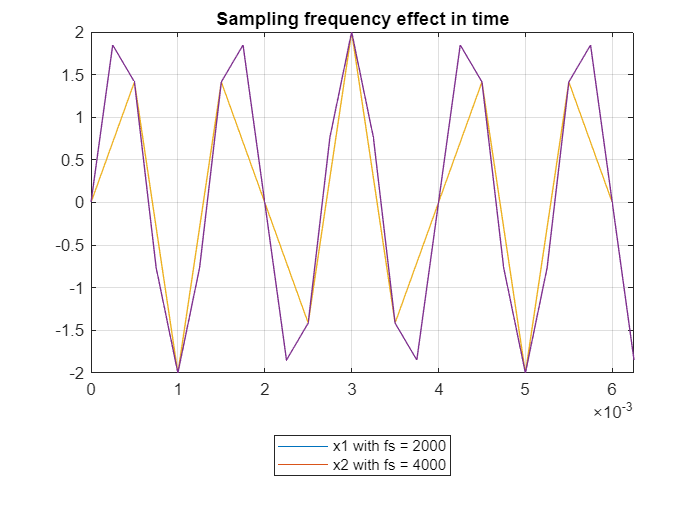

plot(timeIndexes1, x1)
hold on
plot(timeIndexes2, x2)
legend([ 'x1 with fs = ', num2str(fs1) ; 'x2 with fs = ', ...
    num2str(fs2)], 'Location', 'southoutside')
title('Sampling frequency effect in time')
grid on
axis tight


% Comentarios y discusion: 
% + Piense el motivo de la forma de onda que ve al visualizar las señales
% + Piense en el criterio de Nyquist y si el muestreo que hemos hecho
%   lo cumple. 
% + ¿Seria valido un muestreo a esas frecuencias para procesar nuestras
%   señales?

% Se observan tramos lineales (interpolados) que siguen la forma de onda
% original, del tono a 750 Hz. El motivo por el que se ven las señales de
% esta manera es la frecuencia de muestreo seleccionada para ambas pruebas.
% 
% En ambos casos se verifica que la fs es mayor al doble de la señal
% original, es dedir mayor a 1500 Hz. Por ello, es que es posible
% reconstruir la señal a estas tasas. 

% Es válido según el criterio de Nyquist desde el punto de vista de la
% teoría de señales. Sin embargo, visualmente y desde el punto de vista de
% la resolución es limitada. Por lo que se recomendaría aumentar la
% frecuencia de muestreo, por ejemplo a 10 veces la original, 7500 Hz. 

- Genere ahora una señal discreta x3[n], muestreando x(t) a 20KHz, dibújela y compare el resultado con los de x1[n] y x2[n]. Escriba brevemente y en un comentario de su código su observación.

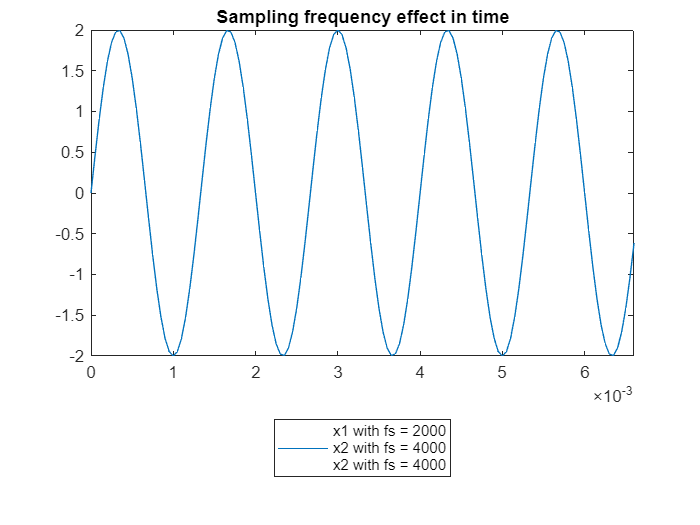

fs3 = 20000;
[ x3, numSamples3, timeIndexes3 ] = generateSignal(fs3, timeDuration, f, amplitude, 0);
plot(timeIndexes3, x3)
legend([ 'x1 with fs = ', num2str(fs1) ; ...
    'x2 with fs = ', num2str(fs2) ; 'x2 with fs = ', num2str(fs2)], ...
    'Location', 'southoutside')
title('Sampling frequency effect in time')
axis tight
hold off


% Comentarios y discusion: 
% + Discuta las diferencias observadas
% + Discuta si desde el punto de vista del procesamiento, 
%   la señal muestreada a fs3 es mejor que a fs1 o fs2

% Se ve una señal más definida, fiel a la señal senoidal original
% esperada. Debido a que la frecuencia de muestreo es varias veces la
% frecuencia de la señal original. 

% Al muestrear la señal original, en el espectro se producen copias desplazadas
% un número entero de veces la frecuencia de muestreo. Desde el punto de vista del muestreo, a mayor
% frecuencia de muestreo, cada copia se separa más la una de la otra. Ahora, no siempre esto es eficiente 
% por más que en la gráfica se observe una señal redondeada, o de alta resolución. 
% Es decir, con un filtro modesto podría reconstruir la señal original a partir de lo obtenido en x2[n] con fs a 4 kHz 
% (a pesar de que se vea como señal "chopeada" en la grafica temporal). Sin
% necesidad de que la fs sea varias veces (más de 26 veces) la señal
% original. Salvo que, el objetivo sea representar temporalmente la señal
% redondeada a alta resolución. 



- Dibuje el módulo de la fft de x1[n], x2[n] y x3[n], calcule las frecuencias en las que se encuentra el máximo valor del módulo de la fft y trate de encontrar una justificación a lo que observe. Si quiere puede ir subiendo progresivamente el número de puntos de la FFT y/o la duración de las señales para ver su impacto en el resultado. Escriba brevemente y en un comentario de su código lo que observe y la justificación, incluyendo un comentario sobre las ventajas e inconvenientes de usar frecuencias de muestreo grandes o pequeñas.

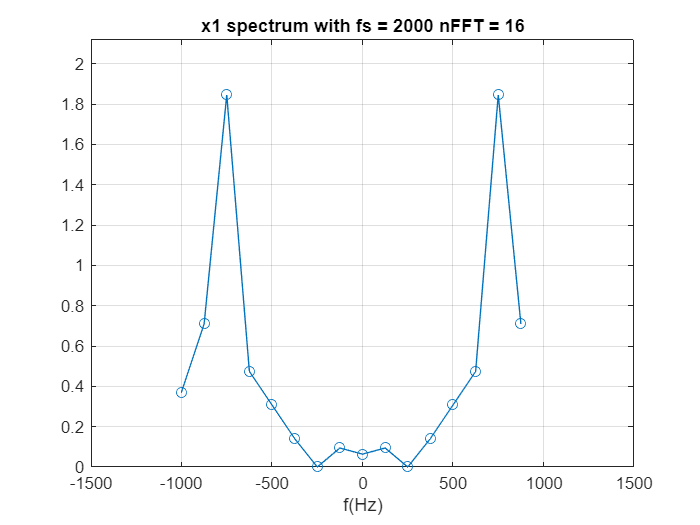

nFFT1 = 2^nextpow2(numSamples1);      % To make the FFT as fast as possible
%nFFT1 = 1024;
fftX1 = 2 * fft(x1, nFFT1) / numSamples1;   % normalize properly
fftX1(1)    = fftX1(1) / 2;
fftX1(end/2+1)  = fftX1(end/2+1) / 2;

fftX1M = fftshift(abs(fftX1));        % shift to have f=0Hz at middle of freq axis 
fftIndexes1 = fs1 / nFFT1 * (-nFFT1/2:(nFFT1/2-1)); % frequency values for each fft sample

plot(fftIndexes1, fftX1M, 'o-')
[M, mIdx] = max(fftX1M);
axis([ -1500 1500 0 M*1.15])
title( ['x1 spectrum with fs = ', num2str(fs1), ' nFFT = ', num2str(nFFT1) ])
xlabel('f(Hz)')
grid on

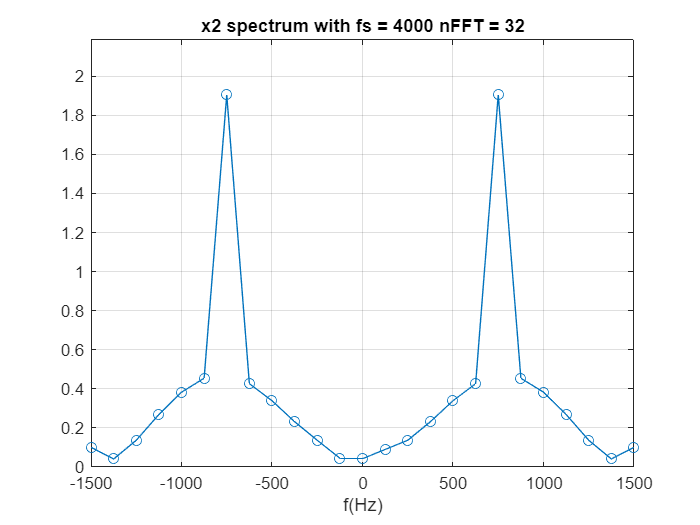

nFFT2 = 2^nextpow2(numSamples2);      % To make the FFT as fast as possible
%nFFT2 = 1024;
fftX2 = 2 * fft(x2, nFFT2) / numSamples2;   % normalize properly
fftX2(1)    = fftX2(1) / 2;
fftX2(end)  = fftX2(end) / 2;
fftX2M = fftshift(abs(fftX2));        % shift to have f=0Hz at middle of freq axis 
fftIndexes2 = fs2 / nFFT2 * (-nFFT2/2:(nFFT2/2-1)); % frequency values for each fft sample

plot(fftIndexes2, fftX2M, 'o-')
[M, mIdx] = max(fftX2M);
axis([ -1500 1500 0 M*1.15])
title( ['x2 spectrum with fs = ', num2str(fs2), ' nFFT = ', num2str(nFFT2) ])
xlabel('f(Hz)')
grid on

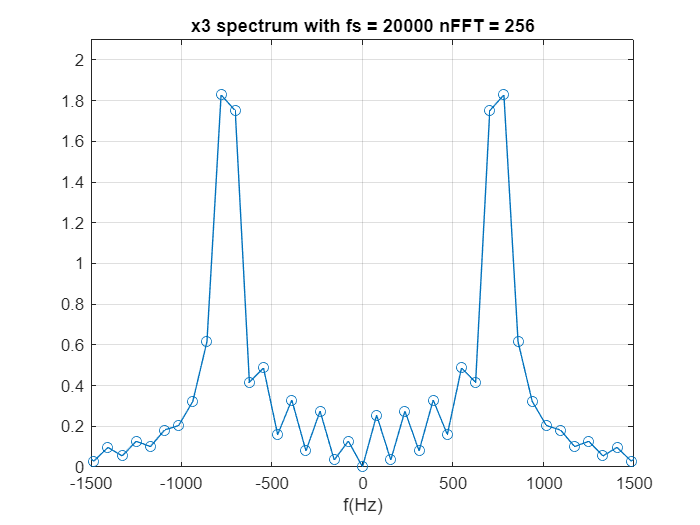

nFFT3 = 2^nextpow2(numSamples3);      % To make the FFT as fast as possible
%nFFT3 = 160;
fftX3 = 2 * fft(x3, nFFT3) / numSamples3;   % normalize properly
fftX3(1)    = fftX3(1) / 2;
fftX3(end)  = fftX3(end) / 2;
fftX3M = fftshift(abs(fftX3));        % shift to have f=0Hz at middle of freq axis 
fftIndexes3 = fs3 / nFFT3 * (-nFFT3/2:(nFFT3/2-1)); % frequency values for each fft sample

plot(fftIndexes3, fftX3M, 'o-')
[M, mIdx] = max(fftX3M);
axis([ -1500 1500 0 M*1.15])
xlim([ -1500 1500 ]);
title( ['x3 spectrum with fs = ', num2str(fs3), ' nFFT = ', num2str(nFFT3) ])
xlabel('f(Hz)')
grid on


% Comentarios y discusion: 
% + Discuta y justifique si a medida que aumentamos la frecuencia de muestreo
%   deberia mejorar la representacion espectral, teniendo en cuenta como siempre
%   la teoria vista en clase.
% + Discuta las ventajas e inconvenientes de trabajar con frecuencias de
%   muestreo grandes o pequeñas

% El calculo de la fft en el primer caso se toma a 16 puntos, la segunda a
% 32 y la final a 256. Como primera observación, al aumentar el tamaño de
% la ventana para que sea mayor o igual al tamaño de las muestras de entrada permite 
% obtener fielmente la representación espectral. Ya que si se tomaba una de
% 16 puntos para el tercer caso, se pierde toda información espectral
% relevante. 

% Repecto a la mejora espectral al aumentar fs, la respuesta es que no
% necesariamente. De hecho al mismo N, aumentar fs quita resolución
% espectral a la fft. Es una relación de compromiso fs/N. No simplemente
% fs. Como el tercer caso presenta mayor resolucion, se observa con mayor
% fidelidad la representación tipo sinc que en los casos anteriores. 

% Para lograr una misma resolución aumentando la fs, debe aumentarse en la
% misa proporción el tamaño de la ventan N, lo cual esto útlimo muchas
% veces es computacionalmente ineficiente o directamente no implementable.
% Siempre verificando Nyquist. 